clear;

% Check your location
if isfolder('D:\Work Files\MATLAB\labW3_codes\IMU')
    addpath(genpath('D:\Work Files\MATLAB\labW3_codes\IMU'))
    disp('You are in the correct directory. Please continue.')
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## **导入传感器数据 Importing sensor data**

data = readtable('train.csv\train.csv');

back_x = data.Feature_1;  % Back sensor acceleration
back_y = data.Feature_2;  
back_z = data.Feature_3;  
thigh_x = data.Feature_4; % Thigh sensor acceleration
thigh_y = data.Feature_5;
thigh_z = data.Feature_6;
Activitytrain = data.Activity; % Activity lable

## 数据预处理（转为二维）Data preprocessing (2D conversion)

% Mean and standard deviation of data from each sensor
backX_mean = mean(back_x, 2);
backY_mean = mean(back_y, 2);
backZ_mean = mean(back_z, 2);
thighX_mean = mean(thigh_x, 2);
thighY_mean = mean(thigh_y, 2);
thighZ_mean = mean(thigh_z, 2);

backX_std = std(back_x, [], 2);
backY_std = std(back_y, [], 2);
backZ_std = std(back_z, [], 2);
thighX_std = std(thigh_x, [], 2);
thighY_std = std(thigh_y, [], 2);
thighZ_std = std(thigh_z, [], 2);

% Combine into a single data
ActivityDataTrain = [backX_mean backY_mean backZ_mean backX_std backY_std backZ_std ...
    thighX_mean thighY_mean thighZ_mean thighX_std thighY_std thighZ_std];

clear backX_mean backY_mean backZ_mean backX_std backY_std backZ_std thighX_mean thighY_mean thighZ_mean thighX_std thighY_std thighZ_std;


## K-Means聚类  K-Means clustering

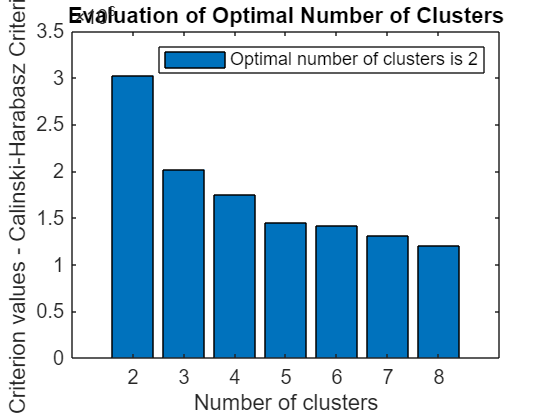

% Make sure the result is the same for each run (set the random seed)
rng('default');

fh = @(X, K) kmeans(X, K);  % Clustering function
eva = evalclusters(ActivityDataTrain, fh, "CalinskiHarabasz", "KList", 2:8); % Use the Calinski-Harabasz metric

K = eva.OptimalK; % Obtain the optimal number of clusters
clusterIndices = eva.OptimalY; % Get the clustering results

figure;
bar(eva.InspectedK, eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - Calinski-Harabasz Criterion");
legend("Optimal number of clusters is " + num2str(K));
title("Evaluation of Optimal Number of Clusters");

disp("Optimal number of clusters is " + num2str(K));

Optimal number of clusters is 2


clear eva fh K;

## 显示聚类的中心及其PCA（主成分分析）结果  PCA (Principal Component analysis) results

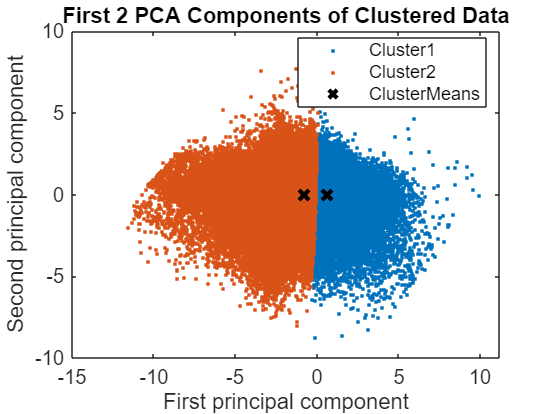

% Displays the centers of the clusters
centroids = grpstats(ActivityDataTrain, clusterIndices, "mean");

figure;
[~, score] = pca(ActivityDataTrain);
clusterMeans = grpstats(score, clusterIndices, "mean");
h = gscatter(score(:, 1), score(:, 2), clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster", h(i).DisplayName);
end
clear h i score;
hold on;
h = scatter(clusterMeans(:, 1), clusterMeans(:, 2), 50, "kx", "LineWidth", 2);
hold off;
h.DisplayName = "ClusterMeans";
clear h clusterMeans;
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## 模型评估 Model evaluation

% Get the index for each cluster and see the corresponding activity
idx_cl1 = clusterIndices == 1;
idx_cl2 = clusterIndices == 2;

% Get the activity label for each cluster
Activity = string(Activitytrain);
act_1 = Activity(idx_cl1); % cluster1
act_2 = Activity(idx_cl2); % cluster2

all_activities = [act_1; act_2];

disp('Cluster 1 activities:');

Cluster 1 activities:


unique_act_1 = unique(act_1); 
for i = 1:length(unique_act_1)
    count_act_1 = sum(act_1 == unique_act_1(i)); 
    disp([char(unique_act_1(i)), ': ', num2str(count_act_1)]); 
end

1: 124650
13: 78283
130: 3326
14: 3282
140: 589
2: 58845
3: 7005
4: 5308
5: 7023
6: 11078
7: 2378646
8: 246803



disp('Cluster 2 activities:');

Cluster 2 activities:


unique_act_2 = unique(act_2);
for i = 1:length(unique_act_2)
    count_act_2 = sum(act_2 == unique_act_2(i)); 
    disp([char(unique_act_2(i)), ': ', num2str(count_act_2)]); 
end

1: 882967
13: 238650
130: 29044
14: 35526
140: 5766
2: 155510
3: 193999
4: 54987
5: 47144
6: 593298
7: 37390
8: 68877


unique_activities = unique(all_activities);
disp('Total activities count across all clusters:');

Total activities count across all clusters:


for i = 1:length(unique_activities)

    total_count = sum(all_activities == unique_activities(i));

    % Define a mapping table that maps numeric labels to activity names
    activity_labels = containers.Map(...
        {'1', '2', '3', '4', '5', '6', '7', '8', '13', '14', '130', '140'}, ...  
        {'Walking', 'Running', 'Jumping', 'Standing', 'Sitting', 'Lying', 'Cycling', 'Hiking', 'Swimming', 'Climbing', 'Dancing', 'Reading'}); % 活动名称
    
    % Replace the number with the corresponding activity name with the mapping table
    
    if isKey(activity_labels, unique_activities(i))
        unique_activities(i) = activity_labels(unique_activities(i));
    end


    disp([char(unique_activities(i)), ': ', num2str(total_count)]); 
end

Walking: 1007617
Swimming: 316933
Dancing: 32370
Climbing: 38808
Reading: 6355
Running: 214355
Jumping: 201004
Standing: 60295
Sitting: 54167
Lying: 604376
Cycling: 2416036
Hiking: 315680


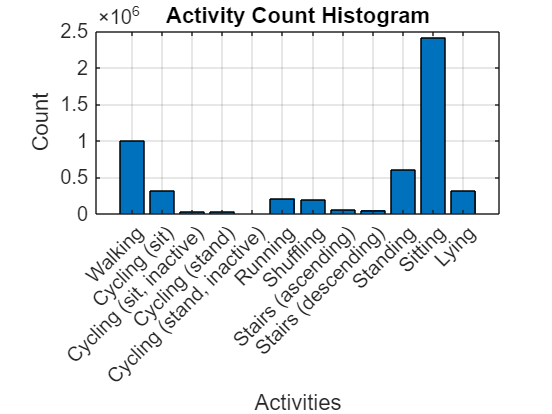

unique_activities = unique(all_activities);  

activity_labels = containers.Map(...
    {'1', '2', '3', '4', '5', '6', '7', '8', '13', '14', '130', '140'}, ... 
    {'Walking', 'Running', 'Shuffling', 'Stairs (ascending)', 'Stairs (descending)', ...
     'Standing', 'Sitting', 'Lying', 'Cycling (sit)', 'Cycling (stand)', ...
     'Cycling (sit, inactive)', 'Cycling (stand, inactive)'}); 

activity_counts = zeros(length(unique_activities), 1);
activity_names = cell(length(unique_activities), 1);

for i = 1:length(unique_activities)

    total_count = sum(all_activities == unique_activities(i));

    if isKey(activity_labels, unique_activities(i))
        activity_names{i} = activity_labels(unique_activities(i));
    else
        activity_names{i} = 'Unknown'; 
    end
    
    activity_counts(i) = total_count;
end


figure;
bar(activity_counts); 

title('Activity Count Histogram');
xlabel('Activities');
ylabel('Count');

set(gca, 'XTickLabel', activity_names, 'XTick', 1:length(activity_names));

xtickangle(45);

grid on;